# **Read and Write CAN Messages with Arduino Hardware**

This example shows you how to use the MATLAB® Support Package for Arduino® Hardware to read and write data from the CAN network using the specified CAN device. 

## Required Hardware

To run this example, you must have the following hardware:

- Sparkfun CAN-Bus Shield

- Arduino Uno

- MKR CAN Shield

- Arduino MKR1000

Connect the CAN Shields to the Arduino boards. The two Arduino boards form a CAN network. In this example, the Arduino Uno is used as a transmitter, and the Arduino MKR1000 is used as a receiver. Connect the `CANH` and `CANL` pins in the two shields to complete the connection. 

This figure shows an example of connection for CAN communication between MKR CAN Shield and Sparkfun CAN-Bus Shield.

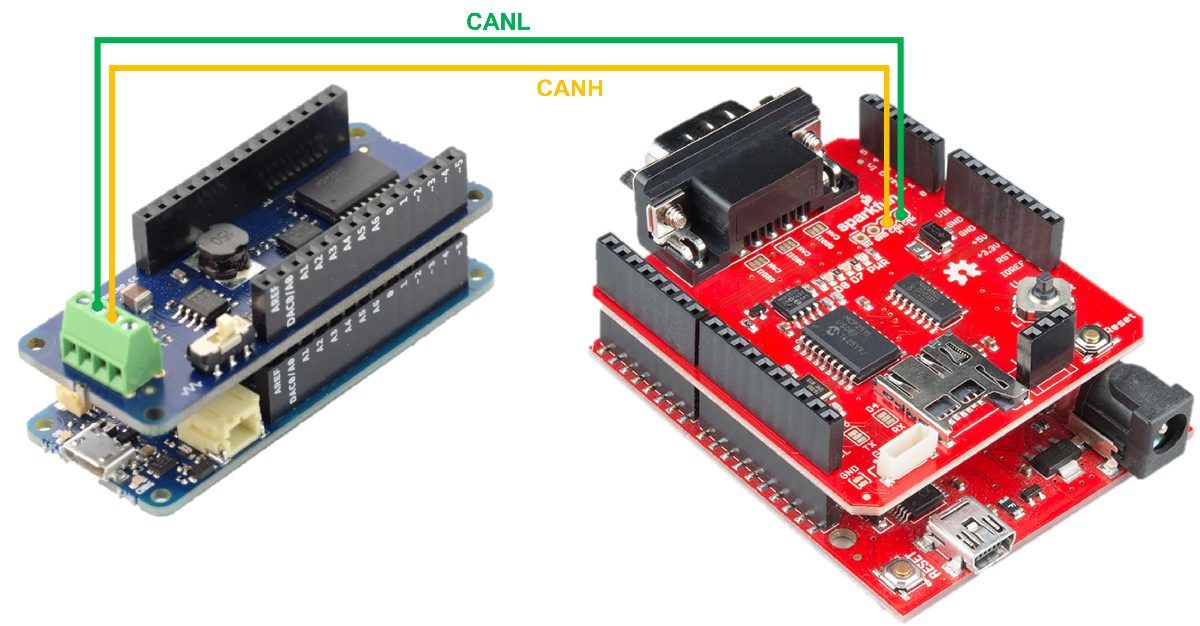

## Create Connection to CAN Channel to Write CAN Messages

Create an arduino object with the Arduino Uno board and include the `CAN` library.

arduinoUnoObj = arduino('COM15','Uno','Libraries','CAN')

 Create a CAN channel object connected to the Sparkfun CAN-Bus Shield to write messages. 

txObj = canChannel(arduinoUnoObj,'MCP2515','D10','D2')

## Create Channel to Read CAN Messages

Create a connection to the Arduino MKR1000 board with the `CAN` library.

arduinoMKRObj = arduino('COM5','MKR1000','Libraries','CAN')

 Create a CAN channel object connected to the MKR CAN Shield to read messages. 

rxObj = canChannel(arduinoMKRObj,'MKR CAN Shield')

## Write Data from Transmitter CAN Channel Object 

Write a CAN message into the channel.

write(txObj, 100, false, [1:8])

## Read Data from Receiver CAN Channel Object

Read the CAN message from the channel.

readMsg = read(rxObj)
readMsg.Data
readMsg.Data{:}

## Clean Up

When finished, clear the connections to the hardware.

clear txObj;
clear arduinoUnoObj;
clear rxObj;
clear arduinoMKRObj;

*Copyright 2019 The MathWorks, Inc.*